# Variabili aleatorie

## Calcoli su una v.a. note le funzioni pdf, cdf, icdf

% Dati
% f = @(x) % pdf
% F = @(x) % cdf
% invF = @(alpha) % icdf
% Nx = numero di valori di x da considerare nei calcoli
% xmin = minimo valore di x da considerare nei calcoli
% xmax = massimo valore di x da considerare nei calcoli
% a1 = estremo sinistro dell'intervallo di cui calcolare la probabilità
% b1 = estremo destro dell'intervallo di cui calcolare la probabilità
% P_left = probabilità a sinistra dell'intervallo da calcolare
% P = probabilità dell'intervallo da calcolare

% Domande
% <fare grafici di pdf, cdf, icdf>

% MOMENTI
% x = Nx valori di x equispaziati tra xmin e xmax
% fX = valori della pdf in x
% nrm = momento di ordine 0 (normalizzazione)
% mu = momento di ordine 1 (media)
% P = momento di ordine 2 (potenza)
% sigma2 = momento centrale di ordine 2 (varianza)
% sigma = deviazione standard
% <fare grafico di pdf con mu e mu+-sigma>

% PROB DI UN INTERVALLO
% pab1 = probabilità dell'intervallo [a1,b1]
% <fare grafico di pdf con l'intervallo [a1,b1]>

% INTERVALLI DATE LE PROB
% a2 = estremo sinistro dell'intervallo di prob. P con probabilità a sinistra Pleft
% b2 = estremo destro dell'intervallo di prob. P con probabilità a sinistra Pleft
% <fare grafico di pdf con l'intervallo [a2,b2]>
% a3 = estremo sinistro dell'intervallo di prob. P a code di area uguale
% b3 = estremo destro dell'intervallo di prob. P a code di area uguale
% <fare grafico di pdf con l'intervallo [a2,b2]>

% INDICI DI POSIZIONE
% moda = moda della v.a.
% mediana = mediana della v.a.
% <fare grafico di pdf con moda, mediana, media>

% INDICI DI DISPERSIONE
% MAD = mean absolute deviation (from mean)
% IQR = interquartile range

% ALTRI INDICI
% sk = skewness
% exku =  excess kurtosis


% Codice iniziale
clear
n = 3; mu1 = 3; % parametri della pdf
f = @(x) gampdf(x,n,mu1) % pdf

f = function_handle with value:
    @(x)gampdf(x,n,mu1)


F = @(x) gamcdf(x,n,mu1) % cdf

F = function_handle with value:
    @(x)gamcdf(x,n,mu1)


invF = @(alpha) gaminv(alpha,n,mu1) % icdf

invF = function_handle with value:
    @(alpha)gaminv(alpha,n,mu1)


Nx = 1e5+1 % numero di valori di x e di alpha da considerare

Nx = 100001

xmin = -10

xmin = -10

xmax = 50 % valori di x da considerare

xmax = 50

a1 = 3, b1 = 25 % estremi di intervallo

a1 = 3

b1 = 25

p_left = 0.1

p_left = 0.1000

p = 0.6

p = 0.6000

### Grafici

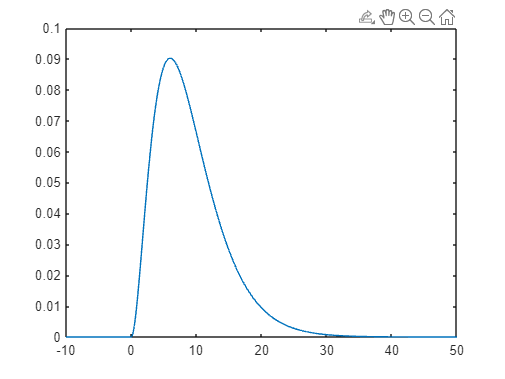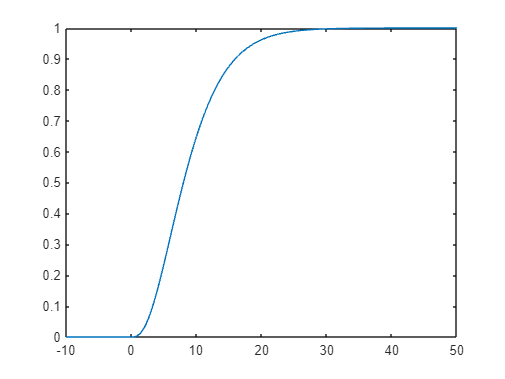

x = linspace(xmin, xmax, Nx)

x =   -10.0000   -9.9994   -9.9988   -9.9982   -9.9976   -9.9970   -9.9964   -9.9958   -9.9952   -9.9946   -9.9940   -9.9934   -9.9928   -9.9922   -9.9916   -9.9910   -9.9904   -9.9898   -9.9892   -9.9886   -9.9880   -9.9874   -9.9868   -9.9862   -9.9856   -9.9850   -9.9844   -9.9838   -9.9832   -9.9826   -9.9820   -9.9814   -9.9808   -9.9802   -9.9796   -9.9790   -9.9784   -9.9778   -9.9772   -9.9766   -9.9760   -9.9754   -9.9748   -9.9742   -9.9736   -9.9730   -9.9724   -9.9718   -9.9712   -9.9706


f(x)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot(x,f(x))
plot(x,F(x))
alpha = linspace(0, 1, Nx)
plot(alpha,invF(alpha))
plot(F(x),x) %stesso grafico di invF(alpha)
%plot(x,sin(x)) esempio funzione built-in

### Momenti

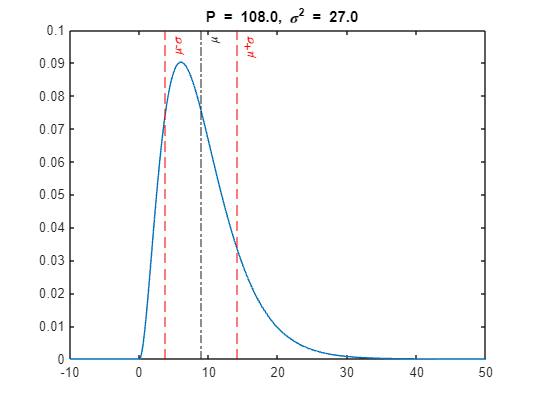

fX = f(x)

fX =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dx = x(2)-x(1) %incremento infinitesimo

dx = 6.0000e-04

nrm = sum(fX*dx)

nrm = 1.0000

mu = sum(x.*fX*dx)

mu = 8.9995

P = sum(x.^2.*fX*dx)

P = 107.9741

sigma2 = P - mu^2

sigma2 = 26.9828

sigman2 = sum((x-mu).^2.*fX*dx)

sigman2 = 26.9821

sigma = sqrt(sigma2)
mu0 = n*mu1 % valore teorico

mu0 = 9

P0 = (n+n^2)*mu1^2 % valore teorico

P0 = 108

sigma20 = n*mu1^2 % valore teorico

sigma20 = 27

plot(x,fX)
xline(mu,'-.','\mu')

xline(mu+sigma,'--r','\mu+\sigma')
xline(mu-sigma,'--r','\mu-\sigma')

titolo = sprintf(' P = %.1f, \\sigma^2 = %.1f',P,sigma2)
title(titolo)

### Probabilità di un intervallo

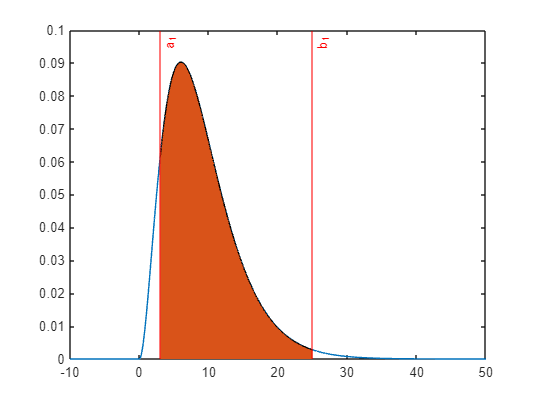

%PROB DI UN INTERVALLO
% pab1 = probabilità dell'intervallo [a1,b1]
a1

a1 = 3

b1

b1 = 25

pab1 = F(b1) - F(a1)

pab1 = 0.9091

plot(x,fX)
xline(a1,'r','a_1')
xline(b1,'r','b_1')

xab1 = linspace(a1,b1,Nx); %valori equispaziati compresi tra a1 e b1
hold on, area(xab1,f(xab1)), hold off

### Intervallo data la probabilità e la probabilità sinistra

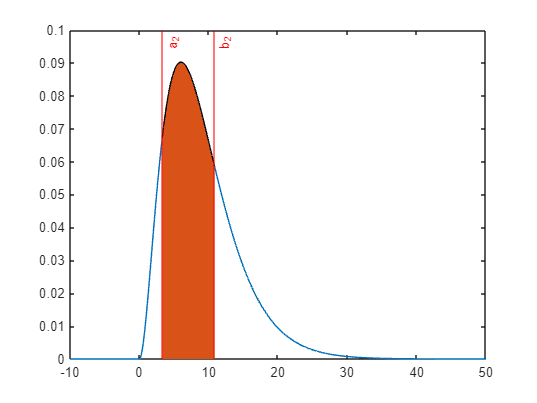

%INTERVALLI DATE LE PROB
%a2 = estremo sinistro dell'intervallo di prob. p con probabilità a sinistra
%pleft
%b2 = estremo destro dell'intervallo di prob. p con probabilità a sinistra
p_left

p_left = 0.1000

p

p = 0.6000

a2 = invF(p_left)

a2 = 3.3062

b2 = invF(p_left+p)

b2 = 10.8467

plot(x,fX)
xline(a2,'r','a_2')
xline(b2,'r','b_2')

xab2 = linspace(a2,b2,Nx);
hold on, area(xab2,f(xab2)), hold off

### Intervallo simmetrico (a code di probabilità uguale) data la probabilità

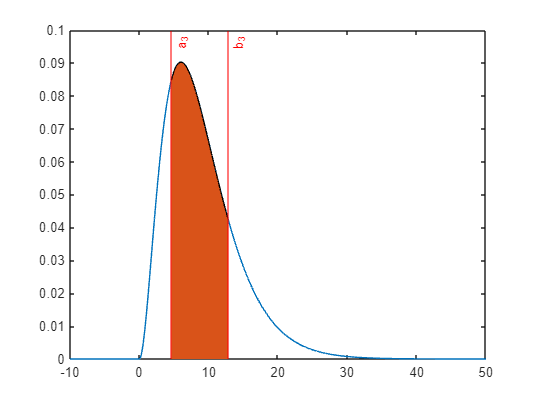

%a3 = estremo sinistro dell'intervallo di prob. p a code di area uguale
%b3 = estremo destro dell'intervallo di prob. p a code di area uguale
a3 = invF((1-p)/2)

a3 = 4.6051

b3 = invF((1+p)/2)

b3 = 12.8371

plot(x,fX)
xline(a3,'r','a_3')
xline(b3,'r','b_3')

xab3 = linspace(a3,b3,Nx);
hold on, area(xab3,f(xab3)), hold off

### Indici di posizione

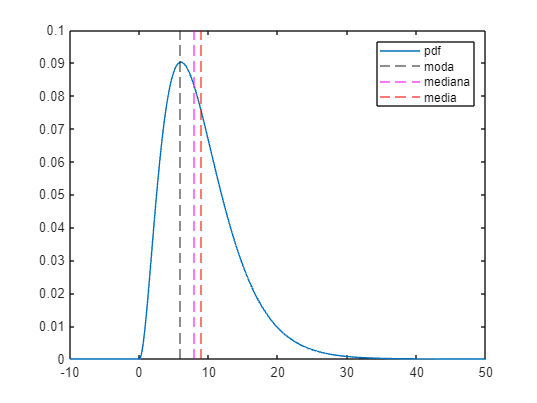

%INDICI DI POSIZIONE
[maxf, i] = max(fX) %i = indice in cui FX assume il valore massimo

maxf = 0.0902

i = 26668

moda = x(i)

moda = 6.0002

mediana = invF(0.5)

mediana = 8.0222

plot(x,fX)
xline(moda,'--')
xline(mediana,'--m')
xline(mu,'--r')
legend('pdf','moda','mediana','media')

### Indici di dispersione

%MAD = mean absolute deviation E(abs(x-mu))
%IQR = interquartile range
MAD = sum(abs(x-mu).*fX*dx)

MAD = 4.0323

IQR = invF(0.75) - invF(0.25)

IQR = 6.5793

### Skewness e curtosi (opzionali)

$s=E\frac{\left\lbrack {\left(X-\mu \;\right)}^3 \right\rbrack }{\sigma^3 }$; $k=E\frac{\left\lbrack {\left(X-\mu \;\right)}^4 \right\rbrack }{\sigma^4 }$

## Calcoli su una v.a. nota una popolazione di valori

% Dati
% X = popolazione di valori
% a1 = estremo sinistro dell'intervallo di cui calcolare la probabilità
% b1 = estremo destro dell'intervallo di cui calcolare la probabilità
% P_left = probabilità a sinistra dell'intervallo da calcolare
% P = probabilità dell'intervallo da calcolare

% Domande
% <fare grafici di cdf, icdf, pdf>

% MOMENTI
% nrm = momento di ordine 0 (normalizzazione)
% mu = momento di ordine 1 (media)
% P = momento di ordine 2 (potenza)
% sigma2 = momento centrale di ordine 2 (varianza)
% sigma = deviazione standard
% <fare grafico di pdf con mu e mu+-sigma>

% PROB DI UN INTERVALLO
% pab1 = probabilità dell'intervallo [a1,b1]
% <fare grafico di pdf con l'intervallo [a1,b1]>

% INTERVALLI DATE LE PROB
% a2 = estremo sinistro dell'intervallo di prob. P con probabilità a sinistra Pleft
% b2 = estremo destro dell'intervallo di prob. P con probabilità a sinistra Pleft
% <fare grafico di pdf con l'intervallo [a2,b2]>
% a3 = estremo sinistro dell'intervallo di prob. P a code di area uguale
% b3 = estremo destro dell'intervallo di prob. P a code di area uguale
% <fare grafico di pdf con l'intervallo [a2,b2]>

% INDICI DI POSIZIONE
% moda = moda della v.a.
% mediana = mediana della v.a.
% <fare grafico di pdf con moda, mediana, media>

% INDICI DI DISPERSIONE
% MAD = mean absolute deviation (from mean)
% IQR = interquartile range

% ALTRI INDICI
% sk = skewness
% exku =  excess kurtosis


% Codice iniziale
clear
n = 3; mu1 = 3; % parametri della pdf
Nsim = 1e6;
X = gamrnd(n,mu1,[1,Nsim])

X =    20.7670   13.0107    3.1516    9.7986   33.9808    7.6951    7.0373   17.7421   17.1449    3.4228   18.9390   14.2149    6.6036    4.7297    3.5936    4.6535   17.3180    4.8423    2.2035    6.8745    9.6327    7.8537   11.4860   14.7577    8.3850    3.6909   18.1022    9.9608   14.8173    8.1606   14.6939    8.4284    4.8867   25.9230   12.2529   13.1907    2.9091   10.6379    7.0775    9.5152   18.5712   11.9210    6.8645    3.5399    8.5249   28.5270    8.9533    1.7753    2.0355    4.3905


a1 = 3, b1 = 25 % estremi di intervallo

a1 = 3

b1 = 25

p_left = 0.1

p_left = 0.1000

p = 0.6

p = 0.6000

### Grafici

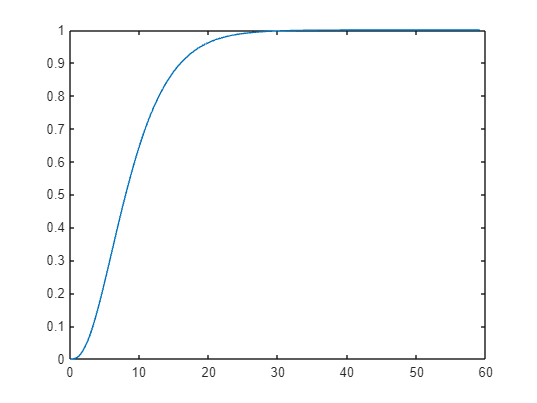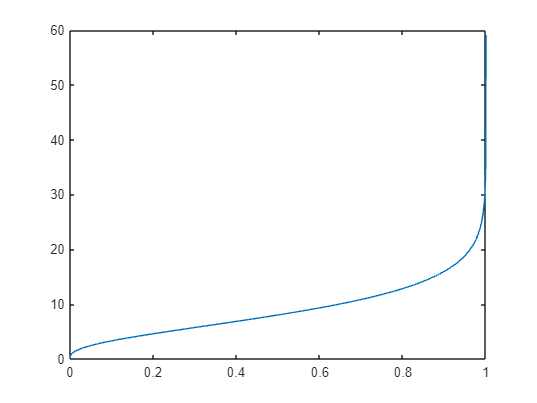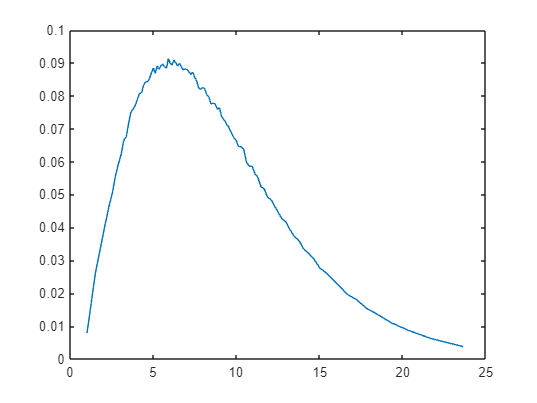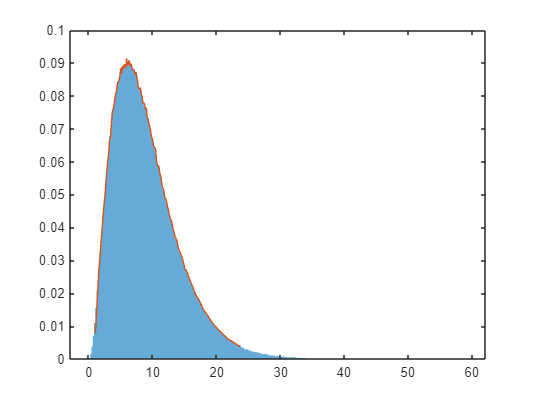

#### cdf

x = sort(X) %ordinamento in ordine crescente

x =     0.0479    0.0704    0.0716    0.0829    0.0959    0.1014    0.1040    0.1063    0.1107    0.1124    0.1156    0.1189    0.1207    0.1336    0.1339    0.1362    0.1409    0.1412    0.1433    0.1492    0.1516    0.1524    0.1537    0.1557    0.1576    0.1603    0.1622    0.1649    0.1695    0.1702    0.1703    0.1703    0.1712    0.1723    0.1734    0.1753    0.1757    0.1767    0.1778    0.1782    0.1826    0.1838    0.1842    0.1858    0.1871    0.1873    0.1991    0.2000    0.2000    0.2006


F = (1:Nsim)/Nsim %cumulativa, secondo logica

F =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001


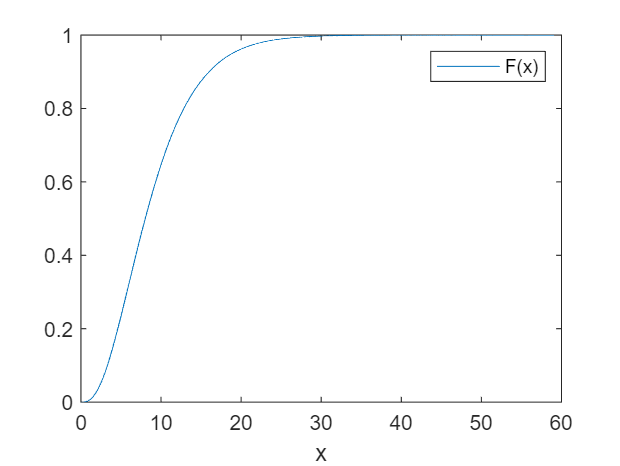


plot(x,F)
xlabel('x')
legend('F(x)')

X %insieme di numeri casuali = popolazione

X =    20.7670   13.0107    3.1516    9.7986   33.9808    7.6951    7.0373   17.7421   17.1449    3.4228   18.9390   14.2149    6.6036    4.7297    3.5936    4.6535   17.3180    4.8423    2.2035    6.8745    9.6327    7.8537   11.4860   14.7577    8.3850    3.6909   18.1022    9.9608   14.8173    8.1606   14.6939    8.4284    4.8867   25.9230   12.2529   13.1907    2.9091   10.6379    7.0775    9.5152   18.5712   11.9210    6.8645    3.5399    8.5249   28.5270    8.9533    1.7753    2.0355    4.3905


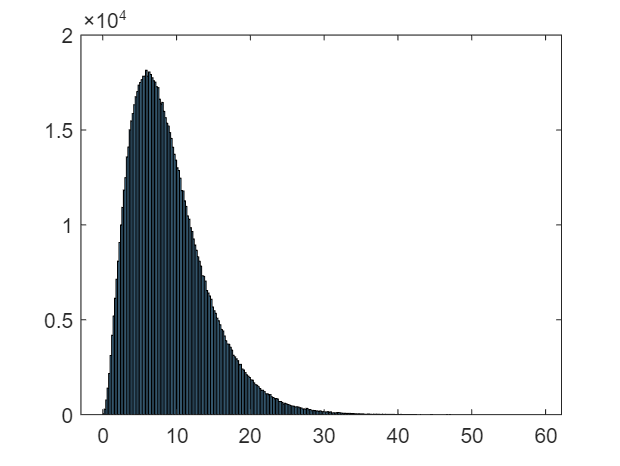

histogram(X)

#### icdf

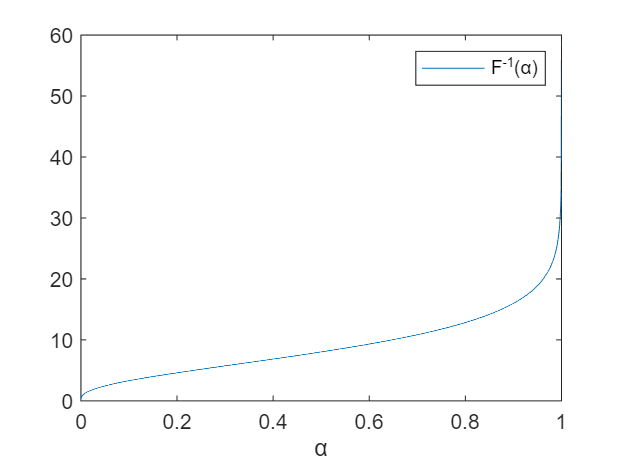

alpha = F;
x_alpha = x;
plot(alpha,x_alpha)
xlabel('\alpha')
legend('F^{-1}(\alpha)')

#### pdf tentativo 1

#### pdf tentativo 2

#### pdf con istogramma

### Momenti


mu0 = n*mu1 % valore teorico
P0 = (n+n^2)*mu1^2 % valore teorico
sigma20 = n*mu1^2 % valore teorico

### Probabilità di un intervallo

### Intervallo data la probabilità e la probabilità sinistra

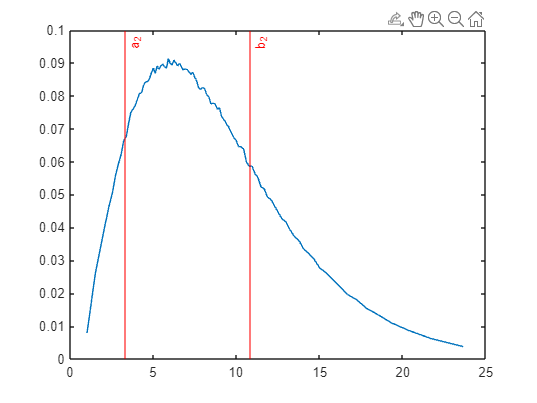

plot(xf,f)
xline(a2,'r','a_2')
xline(b2,'r','b_2')

% xab2 = linspace(a2,b2,Nx);
% hold on, area(xab2,f(xab2)), hold off

### Intervallo simmetrico data la probabilità

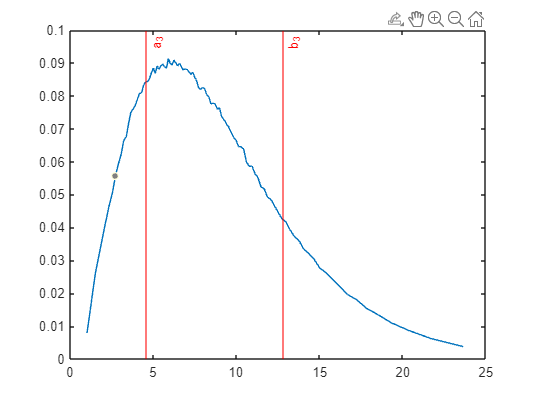

plot(xf,f)
xline(a3,'r','a_3')
xline(b3,'r','b_3')

% xab3 = linspace(a3,b3,Nx);
% hold on, area(xab3,f(xab3)), hold off

### Indici di posizione

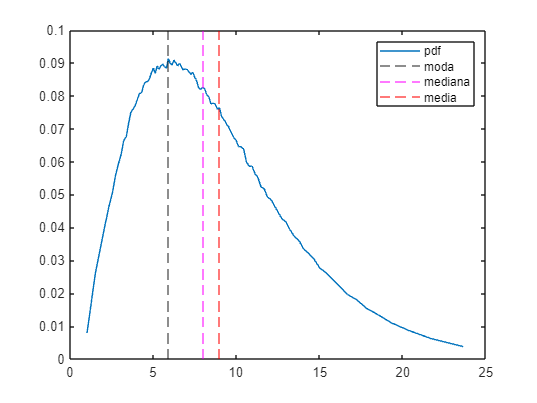


moda0 = (n-1)*mu1 % valore teorico

plot(xf,f)
xline(moda,'--')
xline(mediana,'--m')
xline(mu,'--r')
legend('pdf','moda','mediana','media')

### Indici di dispersione

### Skewness e curtosi

$s=E\frac{\left\lbrack {\left(X-\mu \;\right)}^3 \right\rbrack }{\sigma^3 }$; $k=E\frac{\left\lbrack {\left(X-\mu \;\right)}^4 \right\rbrack }{\sigma^4 }$

sk0 = 2/sqrt(n) % valore teorico

exku0 = 6/n % valore teorico